# Acceleration event_model

syms f1 f2 a w
m=330

m = 330

s0=75

s0 = 75

I=0.239

I = 0.2390

r=0.226

r = 0.2260

T=52

T = 52

alpha=a/r

$$alpha = \frac{500\,a}{113}$$

w_max=7000*2*pi/60

w_max = 733.0383

## *Acceleration in terms of x*

syms x
eqn2= f1*r/2 == I*alpha

$$eqn2 = \frac{113\,f_{1}}{1000}=\frac{239\,a}{226}$$

eqn3= -f2*r/2 == I*alpha - x*T

$$eqn3 = -\frac{113\,f_{2}}{1000}=\frac{239\,a}{226}-52\,x$$

eqn3_a=solve([eqn2 eqn3],[f1 f2])

eqn3_a = struct with fields:
    f1: (119500*a)/12769
    f2: (52000*x)/113 - (119500*a)/12769



eqn4=eqn3_a.f1-eqn3_a.f2==m*a

$$eqn4 = \frac{239000\,a}{12769}-\frac{52000\,x}{113}=330\,a$$

eqn4_a = solve(eqn4,a)

$$eqn4\_a = -\frac{587600\,x}{397477}$$

## *Finding accelearation, time and distance for corresponding gear ratio*

X=1:100

X =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


a_req=zeros(100);
for s=1:100
    a_req(s)=(587600*(s))/397477;
end
a_req

a_req =     1.4783         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.9566         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 


v_max=zeros(100);
for k=1:100
    v_max(k)=(w_max/X(k)) * r;
end
v_max

v_max =   165.6667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   82.8333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 


l_req=zeros(100);
for l=1:100
    l_req(l)=(v_max(l))^2 / (2 * a_req(l));
end
l_req

l_req = 1.0e+03 *

    9.2826         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.1603         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

## *Time_Taken*

time_1=zeros(100);

for i=1:100
    if l_req(i) < s0
        time_1(i) = (v_max(i)/a_req(i)) + (s0-l_req(i))/v_max(i);
        
    else
        time_1(i) = sqrt(2*s0/a_req(i));
    end
end
time_1

time_1 =    10.0730         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.1227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

## *Plotting time_taken vs gear_ratio*

time_2=time_1(:,1)

time_2 =    10.0730
    7.1227
    5.8157
    5.0365
    4.5049
    4.2727
    4.3125
    4.4972
    4.7662
    5.0875


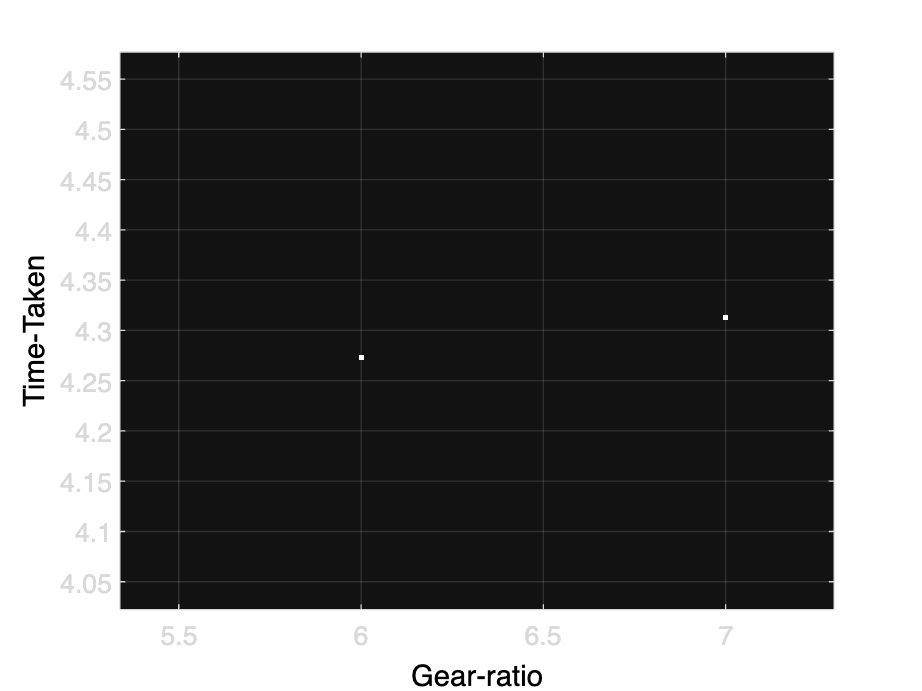

for x=1:25
    plot(x,time_2(x),".w")
    
    grid on
    xlabel("Gear-ratio","Color","k")
    ylabel("Time-Taken","Color","k")
    hold on
end